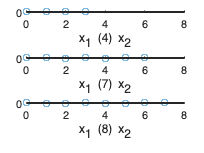

% HW 7 Problem 3 Using the circconvolution.m file 
% 3.1

x1 = [2 1 1 2];
x2 = [1 -1 -1 1];

y4 = circconvolution(x1, x2, 4);
y7 = circconvolution(x1, x2, 7);
y8 = circconvolution(x1, x2, 8);

figure;
subplot(3,1,1);
stem(0:length(y4)-1, y4);
axis([0 8 -3 3]);
xlabel('x_1 (4) x_2');
subplot(3,1,2);
stem(0:length(y7)-1,y7);
axis([0 8 -3 3]);
xlabel('x_1 (7) x_2');
subplot(3,1,3);
stem(0:length(y8)-1,y8);
axis([0 8 -3 3]);
xlabel('x_1 (8) x_2');


% 3.2
figure;
y = conv(x1,x2)'

y =      2
    -1
    -2
     2
    -2
    -1
     2


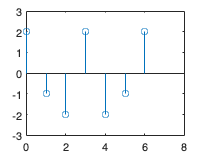

stem(0:length(y)-1, y)
axis([0 8 -3 3]);


% 3.3
% From the figure we see that N >= 7 makes linear and 
% circular convolution equivalent

% 3.4
% The same result can be computed by the formula 
% length(x1) + length(x2) - 1

% HW 7 Prob 4.i

NUMBER_RUNS=5;
N1 = 1024;
N4 = 4096;
h = sin(0.4*pi * 0:99);
Hk1 = fft(h,N1);
Hk4 = fft(h,N4);
LEN=10^8;
tc = 0; tf1 = 0; tf4 = 0; 
for I = 1:NUMBER_RUNS
    x = -1 + 2 .* rand(LEN,1)';
    fprintf("Run %d\n", I);
    t0 = datetime('now'); yc = conv(h,x); t1 = seconds(datetime('now') - t0); fprintf("conv:      %d sec\n", t1);tc = tc + t1;
    t0 = datetime('now'); yf1 = overlapsave(x,h,N1); t1 = seconds(datetime('now') - t0); fprintf("ovlsv1024: %d sec\n", t1); tf1 = tf1 + t1;
    t0 = datetime('now'); yf4 = overlapsave(x,h,N4); t1 = seconds(datetime('now') - t0); fprintf("ovlsv4096: %d sec\n\n", t1); tf4 = tf4 + t1;
end

Run 1


conv:      1.045470e-01 sec


ovlsv1024: 2.633656e+00 sec


ovlsv4096: 2.113149e+00 sec



Run 2


conv:      1.332860e-01 sec


ovlsv1024: 3.167492e+00 sec


ovlsv4096: 2.979560e+00 sec



Run 3


conv:      1.322110e-01 sec


ovlsv1024: 1.333663e+00 sec


ovlsv4096: 3.147451e+00 sec



Run 4


conv:      1.312030e-01 sec


ovlsv1024: 2.502171e+00 sec


ovlsv4096: 1.875962e+00 sec



Run 5


conv:      1.315380e-01 sec


ovlsv1024: 2.792168e+00 sec


ovlsv4096: 1.878533e+00 sec



% 4.i.a
conv_time = tc/NUMBER_RUNS;
% 4.i.b
oversave1024_time = tf1/NUMBER_RUNS;
% 4.i.c
oversave4096_time = tf4/NUMBER_RUNS;
disp('')
fprintf("Final results:\nconv:      %f\novlsv1024: %f\novlsv4096: %f\n", conv_time, oversave1024_time, oversave4096_time)

Final results:
conv:      0.126557
ovlsv1024: 2.485830
ovlsv4096: 2.398931


%4.ii
% conv. disregarding transient conditions, we can approximate
% each point in the output as the convolution of h(n) with x(n)
DL = 10^6;
M = 100;
conv_mult = DL*M % x(n) * h(n) for each n, 0 <= n < 10^7

conv_mult = 100000000


% for overlap and save using 1024, we prepend the input signal with
% 99 zeros (100 - 1), then for N = 1024, the data size within each N
% block is given by L = N - (M - 1) = 1024 - 99 = 925.
% Thus the number of blocks is 10^7/925 = 10810, with 750 remaining points
% we must append zeros so we perform a total of 10811 block. Within each
% block we perform 1 FFT, 1 N multiplication (with H(k)) and 1 iFFT
% thus number of complex multiplications is (N/2 * log2(N))*(1+2*(10811)) + N*10811
% and we multiply the number above by 4 to obtain real multiplications

M1 = M - 1;
N = 1024;
log2N = 10;
L = N - M1;
K = fix(DL/L) + 1

K = 1082

F = (N/2)*log2N

F = 5120

ovlsav1024_mult = 4*((N/2* log2N)*(1+2*K)+ N*K)

ovlsav1024_mult = 48771072


% for N = 4096 
N = 4096;
log2N = 12;
L = N - M1;
K = fix(DL/L) + 1

K = 251

F = (N/2)*log2N

F = 24576

ovlsav4096_mult = 4*((N/2* log2N)*(1+2*K)+ N*K)

ovlsav4096_mult = 53559296

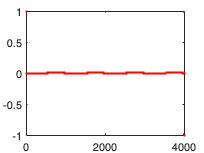

% 5
n = 0:3999;
h = [1 -1 1 -1];
x = cos(pi*n/500);
ys = overlapsave(x,h,16);
ya = overlapadd(x,h,16);
plot(1:length(ys),ys,'b.',1:length(ya),ya,'r.');

ml = min(length(ya),length(ya));
sum(abs(ys(1:ml) - ya(1:ml)))

ans = 5.1468e-13